% AAE364L pre-lab3 
% Tomoki Koike
clear all; close all; clc;
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
setup_lab_ip01_2_sip;

% Get the poles and plot them 

% Pole Placement 
lambda1 = -3+3.5i;
lambda2 = conj(lambda1);
lambda3 = -10;
lambda4 = -15;
lambdas_pp = [lambda1, lambda2, lambda3, lambda4];
K_pp = place(A, B, lambdas_pp)

K_pp =   -47.9001   67.5785  -29.6405    9.5819


K = K_pp;
sim('s_sip_lqr.mdl')

% LQR - Linear Quadratic Regulator 
diagonal = diag([35, 35, 0, 2]);
K_lqr = lqr(A, B, diagonal, 1/100)

K_lqr =   -59.1608  154.4648  -50.4943   25.4244


K = K_lqr;
lambdas_lqr = eig(A-B*K_lqr);
sim('s_sip_lqr.mdl')

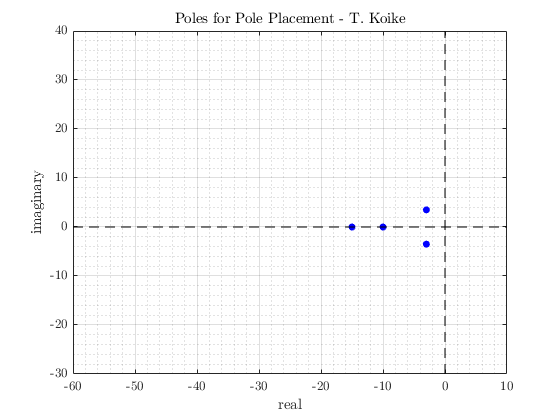

% Plotting 
fig0 = figure();
plot(real(lambdas_pp), imag(lambdas_pp), 'b.', 'MarkerSize', 18)
title('Poles for Pole Placement - T. Koike')
xlabel('real')
ylabel('imaginary')
hold on 
plot(linspace(-60,10,2^6), 0*linspace(-60,10,2^6),'--k')
plot(0*linspace(-30,40,2^6), linspace(-30,40,2^6),'--k')
hold off
grid on; grid minor; box on;
xlim([-60, 10]); ylim([-30, 40]);

fig1 = figure();
plot(real(lambdas_lqr), imag(lambdas_lqr), 'r.', 'MarkerSize', 18)
title('Poles for LQR - T. Koike')
xlabel('real')
ylabel('imaginary')
hold on 
plot(linspace(-60,10,2^6), 0*linspace(-60,10,2^6),'--k')
plot(0*linspace(-30,40,2^6), linspace(-30,40,2^6),'--k')
hold off
grid on; grid minor; box on;
xlim([-60, 10]); ylim([-30, 40]);

saveas(fig0, 'labP_pole_pp.png');

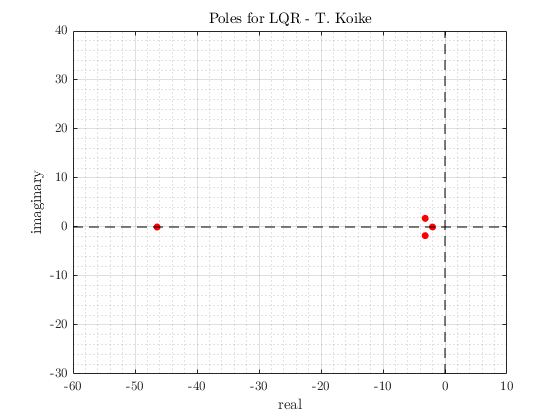

saveas(fig1, 'labP_pole_lqr.png');